

% Load Accel / Gyro Training data
AccelGyroCalib = load("calib2_straight.mat");

% Load Magnetometer data
MagCalib = load("calib1_rotate.mat");


% Extract accelerometer and gyro data
accel = squeeze(permute(AccelGyroCalib.out.Sensor_ACCEL.signals.values, [3, 2, 1]));
gyro  = squeeze(permute(AccelGyroCalib.out.Sensor_GYRO.signals.values, [3, 2, 1]));
t = AccelGyroCalib.out.Sensor_ACCEL.time;
rotQuat = AccelGyroCalib.out.GT_rotation.signals.values;
eulAngles = quat2eul(rotQuat);
yawGT = eulAngles(:,1) + pi;

% Calib1 (rotate) time
t_mag = MagCalib.out.Sensor_MAG.time;


% Extract second accelerometer data
accel2 = squeeze(permute(AccelGyroCalib.out.Sensor_LP_ACCEL.signals.values, [3, 2, 1]));

% Extract Magnetometer Data (rotation)
mag = squeeze(permute(MagCalib.out.Sensor_MAG.signals.values, [3, 2, 1]));


% Do same for still data
mag_still = squeeze(permute(AccelGyroCalib.out.Sensor_MAG.signals.values, [3, 2, 1]));



% Extract TOF data
tof_left = squeeze(AccelGyroCalib.out.Sensor_ToF1.signals.values(:,1,:));
tof_middle  = squeeze(AccelGyroCalib.out.Sensor_ToF2.signals.values(:,1,:));
tof_right = squeeze(AccelGyroCalib.out.Sensor_ToF3.signals.values(:,1,:));


% Define rotation matrices
Rotw_a = [0 1 0;
       0 0 1;
      -1 0 0]; % Accelerometer / Gyro

Rotw_a2 = [1 0 0;
        0 0 -1;
        0 1 0]; % Accelerometer 2

Rotw_mag = [0 1 0;
         0 0 1;
         1 0 0]; % Magnetometer

accel_corrected = (Rotw_a * accel')'; 
gyro_corrected = (Rotw_a * gyro')';

accel2_corrected = (Rotw_a2 * accel2')';

mag_corrected = (Rotw_mag * mag')';

mag_still_corrected = (Rotw_mag * mag_still')';


% Filter data where t < 60
idx = t < 60;  % Logical index where time is less than 60
t = t(idx);
accel_corrected = accel_corrected(idx, :);
gyro_corrected = gyro_corrected(idx,:);

% Extract TOF data and apply time filter
tof_left = tof_left(idx);
tof_middle = tof_middle(idx);
tof_right = tof_right(idx);

accel2_corrected = accel2_corrected(idx, :);

% Find Accelerometer and Gyro Bias and std
accel_bias = mean(accel_corrected);
gyro_bias = mean(gyro_corrected);

accel2_bias = mean(accel2_corrected);

R_accel = cov(accel_corrected);
R_gyro = cov(gyro_corrected);

R_accel2 = cov(accel2_corrected);

% Compute variances (1x1 covariance matrices)
R_tof_left = var(tof_left);
R_tof_middle = var(tof_middle);
R_tof_right = var(tof_right);


% Perform magnetometer calibration
[A_mag, b_mag, ~] = magcal(mag_corrected);

% A_mag: Transformation matrix
% b_mag: Bias vector

mag_corrected = (mag_corrected - b_mag) * A_mag;

mag_still_corrected = (mag_still_corrected - b_mag) * A_mag;


% Use Magnetometer from static data to find std / covariance
R_mag = cov(mag_still);

% Extract yaw angle from static magnetometer
psi_meas = atan2(mag_still_corrected(:,2), mag_still_corrected(:,1));  % atan2(Y, X)

% Wrap to [-pi, pi] to avoid jumps
psi_meas = wrapToPi(psi_meas);

% Estimate yaw variance 
R_psi = var(psi_meas);



% Plot results
% figure(1)
% plot(t, accel_corrected)
% title('Accelerometer Information')
% xlabel('Time (s)')
% ylabel('Acceleration (m/s^2)')
% legend('X', 'Y', 'Z')
% grid on
% 
% figure(2)
% plot(t, gyro_corrected);
% title('Gyroscope Data');
% xlabel('Time (s)');
% ylabel('Angular Velocity (rad/s)');
% legend('X (Roll)', 'Y (Pitch)', 'Z (Yaw)');
% 
% figure(3)
% plot(t, accel2_corrected)
% title('Accelerometer 2 Information')
% xlabel('Time (s)')
% ylabel('Acceleration (m/s^2)')
% legend('X', 'Y', 'Z')
% grid on
% 
% figure;
% plot(t_mag, mag_corrected);
% title('Calibrated Magnetometer Data');
% xlabel('Time (s)');
% ylabel('Magnetic Field (µT)');
% legend('X', 'Y', 'Z');

% Print Accelerometer Covariance Matrix
disp('Accelerometer Covariance Matrix (R_accel):');

Accelerometer Covariance Matrix (R_accel):


disp(R_accel);

   1.0e-03 *

    0.0456   -0.0134   -0.0132
   -0.0134    0.0697    0.0705
   -0.0132    0.0705    0.1909




% Print Gyroscope Covariance Matrix
disp('Gyroscope Covariance Matrix (R_gyro):');

Gyroscope Covariance Matrix (R_gyro):


disp(R_gyro);

   1.0e-05 *

    0.1949    0.0095    0.0017
    0.0095    0.1492    0.0040
    0.0017    0.0040    0.1158




% Print Second Accelerometer Covariance Matrix
disp('Second Accelerometer Covariance Matrix (R_accel2):');

Second Accelerometer Covariance Matrix (R_accel2):


disp(R_accel2);

   1.0e-03 *

    0.1048    0.0287   -0.0165
    0.0287    0.6711   -0.0866
   -0.0165   -0.0866    0.3443




% Print Magnetometer Covariance Matrix
disp('Magnetometer Covariance Matrix (R_mag):');

Magnetometer Covariance Matrix (R_mag):


disp(R_mag);

   1.0e-10 *

    0.0902    0.0374   -0.2280
    0.0374    0.0363   -0.1476
   -0.2280   -0.1476    0.9258




% Display Tof Covariances
disp('ToF Sensor Covariances:');

ToF Sensor Covariances:


disp(['Left ToF: ', num2str(R_tof_left)]);

Left ToF: 4.4603e-06


disp(['Middle ToF: ', num2str(R_tof_middle)]);

Middle ToF: 7.7185e-05


disp(['Right ToF: ', num2str(R_tof_right)]);

Right ToF: 1.6871e-05



% Print Accelerometer Bias
disp('Accelerometer Bias (accel_bias):');

Accelerometer Bias (accel_bias):


disp(accel_bias);

    0.0275   -0.3963  -10.0025




% Print Gyroscope Bias
disp('Gyroscope Bias (gyro_bias):');

Gyroscope Bias (gyro_bias):


disp(gyro_bias);

   -0.0112   -0.0013   -0.0019




% Print Second Accelerometer Bias
disp('Second Accelerometer Bias (accel2_bias):');

Second Accelerometer Bias (accel2_bias):


disp(accel2_bias);

    0.4372    0.3573  -10.2280




% Print Magnetometer Bias (from magcal)
disp('Magnetometer Bias (b_mag):');

Magnetometer Bias (b_mag):


disp(b_mag);

   1.0e-04 *

   -0.5304    0.6372   -0.1037




%% === Magnetometer Interference Correction (X-axis correlation with Accel) ===
% Use the same time-filtered accel_corrected and mag_still_corrected
accel_x = accel_corrected(:,1);                % X-axis of primary accel
mag_x   = mag_still_corrected(:,1);% X-axis of magnetometer (already corrected)

% Sanity check: match lengths
min_len = min(length(accel_x), length(mag_x));
accel_x = accel_x(1:min_len);
mag_x   = mag_x(1:min_len);

% Inverse linear relation: mag_x = offset - alpha * accel_x
% So, fit mag_x vs. -accel_x
[coeffs, ~] = polyfit(-accel_x, mag_x, 1);
alpha_x= coeffs(1)

alpha_x = -4.7632e-07

offset_est_x = coeffs(2)

offset_est_x = 7.7953e-06


accel_y = accel_corrected(:,2);                % X-axis of primary accel
mag_y   = mag_still_corrected(:,2);% X-axis of magnetometer (already corrected)

% Sanity check: match lengths
min_len = min(length(accel_y), length(mag_y));
accel_x = accel_y(1:min_len);
mag_y   = mag_y(1:min_len);

% Inverse linear relation: mag_x = offset - alpha * accel_x
% So, fit mag_x vs. -accel_x
[coeffs, ~] = polyfit(-accel_y, mag_y, 1);
alpha_y = coeffs(1)

alpha_y = -4.5182e-07

offset_est_y = coeffs(2)

offset_est_y = 4.6400e-06

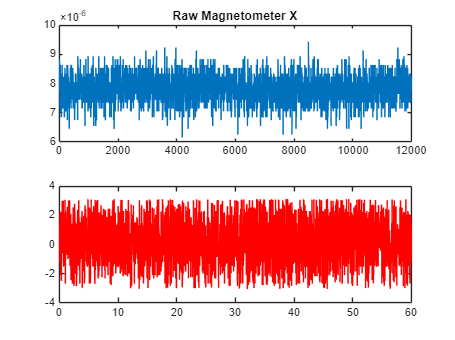


% Optional: visualize
mag_x_corr = mag_x - offset_est_x + alpha_x * accel_x;  % Apply correction
mag_y_corr = mag_y - offset_est_y + alpha_y * accel_y;  % Apply correction
figure;
subplot(2,1,1);
plot(mag_x); title('Raw Magnetometer X');
subplot(2,1,2);
plot(mag_x_corr); title('Corrected Magnetometer X (approx)');

%% Debug: Plot magnetometer yaw (raw) vs. GT yaw
mag_yaw = wrapToPi(atan2(mag_y_corr, mag_x_corr));
figure(4)
plot(t, mag_yaw, 'r'); hold on;

plot(t, wrapToPi(yawGT), 'k');

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

legend('Magnetometer yaw', 'GT yaw');
title('Magnetometer vs Ground Truth Yaw');
xlabel('Time [s]'); ylabel('Yaw [rad]');


% Save to .mat file
save('sensor_calibration2.mat', 'R_accel', 'R_gyro', 'R_accel2', 'R_mag', ...
    'accel_bias', 'gyro_bias', 'accel2_bias', 'b_mag', ...
    'R_tof_left', 'R_tof_middle', 'R_tof_right','Rotw_mag','Rotw_a','Rotw_a2','A_mag','b_mag', 'R_psi');

% Save for use in EKF
save('sensor_calibration2.mat', '-append', 'alpha_x', 'alpha_y');